clear all, close all;
folder = {'descriptor','external_code','Results'};
for it=1:length(folder)
    p = genpath(folder{it});
    addpath(p);
end

results = dir('Results');
%R = struct.empty(4,0);
for i = 3:length(results)
    results(i).name
    R(i-2) = load(results(i).name);   
end

ans = 'EHD_restults_.mat'

ans = 'HOG_results_.mat'

ans = 'LGHD_restults.mat'

ans = 'R2D2_results16.mat'

ans = 'R2D2_results32.mat'

ans = 'R2D2_results47.mat'

ans = 'R2D2_results47_2.mat'

ans = 'R2D2_results47_2G.mat'

ans = 'R2D2_results47_gmBi.mat'

ans = 'R2D2_results47_gminv.mat'

ans = 'R2D2_results47_vpts.mat'

ans = 'R2D2_results47_vpts2.mat'

ans = 'R2D2_results47gm.mat'

ans = 'R2D2_results64.mat'

ans = 'R2D2_results64G.mat'

ans = 'R2D2_results64gm.mat'

ans = 'R2D2_results8.mat'

ans = 'R2D2_results80.mat'

ans = 'R2D2_results96.mat'

ans = 'RIFT_results_ori_ShiTo.mat'

ans = 'rift_results_ori_fast.mat'

for i = 3:length(results)
    R(i-2).method = results(i).name;
    totError2 = R(i-2).totError(find(R(i-2).totError < 22));
    tre2(i-2) = sum(totError2)/length(totError2);
end
R

R = 1×21 struct array with fields:
    R
    TRE
    descsize
    folder
    i
    it
    meanTime
    miss
    missAmount
    missTab
    nameLwir
    operations
    p
    pointsStat
    pointsStatMiss
    results
    timeExec
    totError
    method


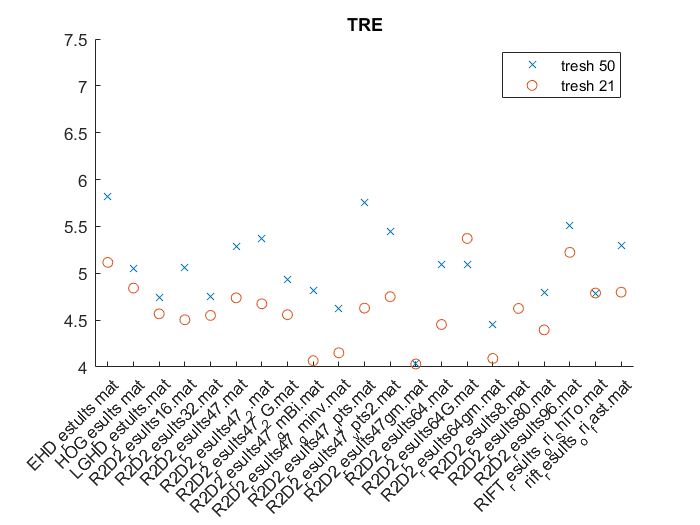

tre = extractfield(R,'TRE');
times = extractfield(R,'meanTime');
operations = extractfield(R,'operations');
methods = extractfield(R,'method');
methods(:) = erase(methods(:),'_results_*.mat');
sizes = extractfield(R,'i');
pointStats = zeros(7,200,4);
which = find(length(methods) < 7);
%index = contains(results(:).name,'R2D2','IgnaoreCase')
prevalence = [];
bigmiss = [];
for i = 1:length(R)
   pointStats(i,:,:) = R(i).pointsStat ;
   bigmiss = [bigmiss R(i).missTab] ;
   mt = R(i).missTab;
  % [pointStats(i,90,:)]
   for j = 1:length(mt)
       index = floor(mt(j)/3);
       pointStats(i,:,:) = cat(2,pointStats(i,1:index-1,:) ,pointStats(i,index:end,:));
   end
   l = sizes(i);
   prevalence(i) = sum((pointStats(i,1:l,3)./pointStats(i,1:l,1)).*100)/l;
   posprevalence(i) = sum((pointStats(i,1:l,4)./pointStats(i,1:l,1)).*100)/l;
   meanNCM(i) = sum(pointStats(i,1:l,4))/l;
   matchpercent(i) = sum((pointStats(i,1:l,4)./pointStats(i,1:l,3)).*100)/l;
%   accuracy(i) = 
   
end

matchingeff = matchpercent./prevalence;
posmatchingeff = matchpercent./posprevalence;
workload = matchpercent./times;
workload2 = matchpercent./(operations/(10^9));
workload_NCM = meanNCM./times;
workload_Pre = prevalence./times;
workload_meff = matchingeff./times;
workload_peff = posmatchingeff./times;
X = categorical(methods);
cats = [3,10,14];
X2 = X([1,3,4,5]);
figure, hold on ,plot(X,tre,'x'),plot(X,tre2,'o'),title('TRE'),legend('tresh 50','tresh 21'), hold off;

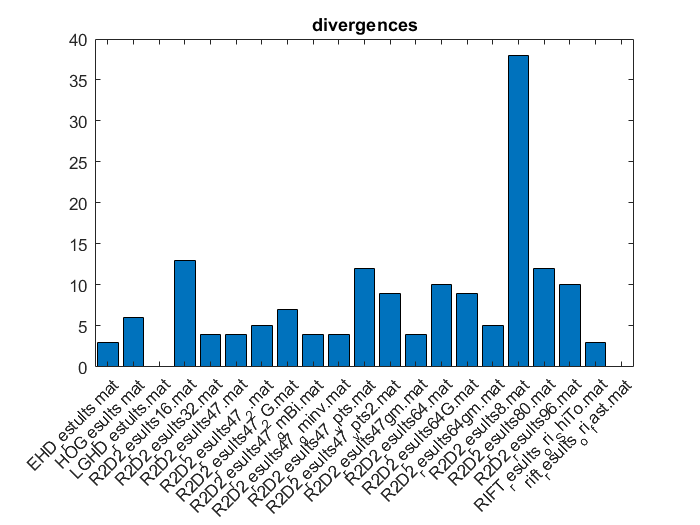

figure, bar(X,extractfield(R,'miss')), title('divergences');

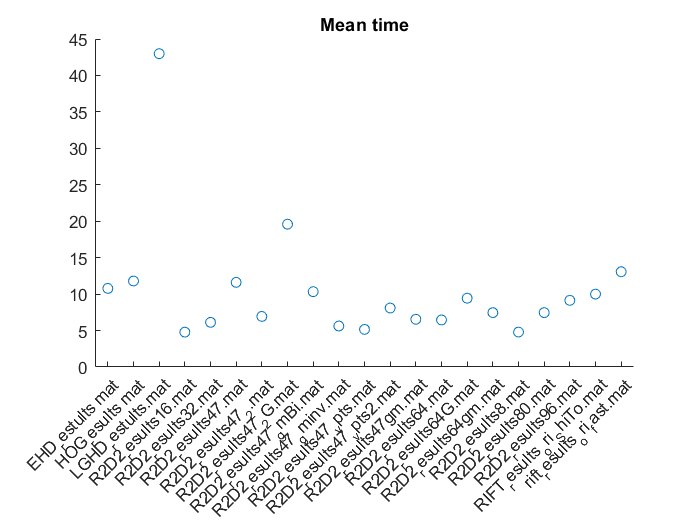

figure, hold on ,plot(X,times,'o'),title('Mean time'), hold off;

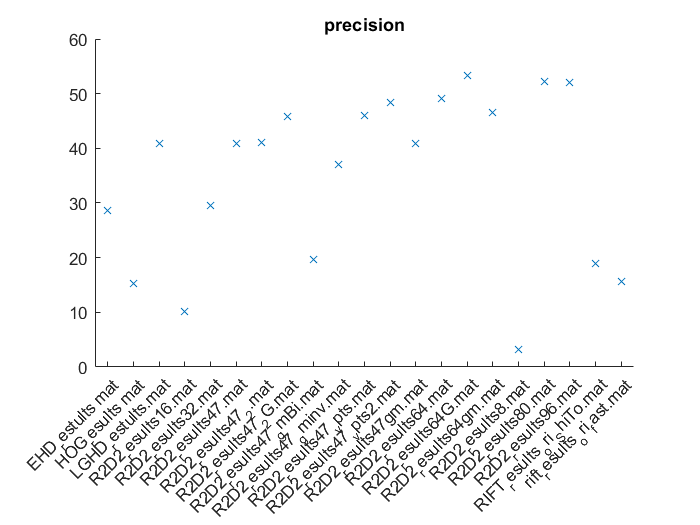

figure, hold on, plot(X,matchpercent,'x'), title('precision'),hold off;

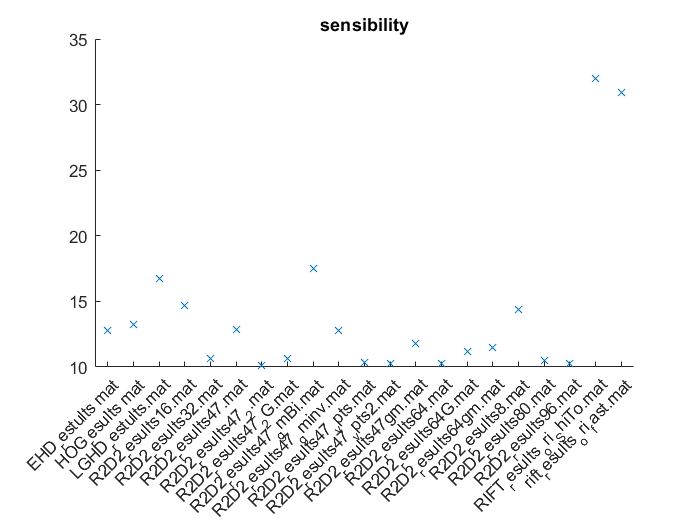

figure, hold on, plot(X,prevalence,'x'), title('sensibility'),hold off;

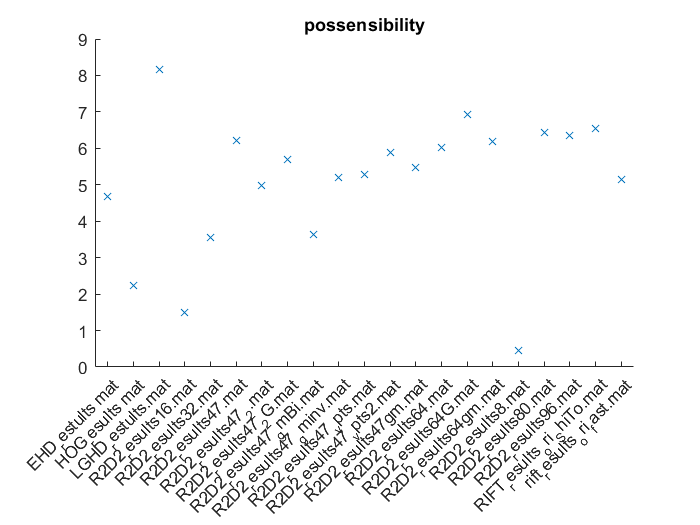

figure, hold on, plot(X,posprevalence,'x'), title('possensibility'),hold off;

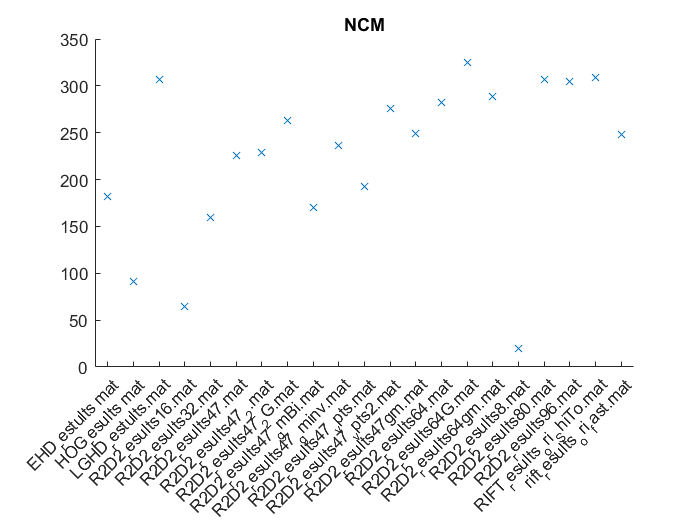

figure, hold on, plot(X,meanNCM,'x'), title('NCM'),hold off;

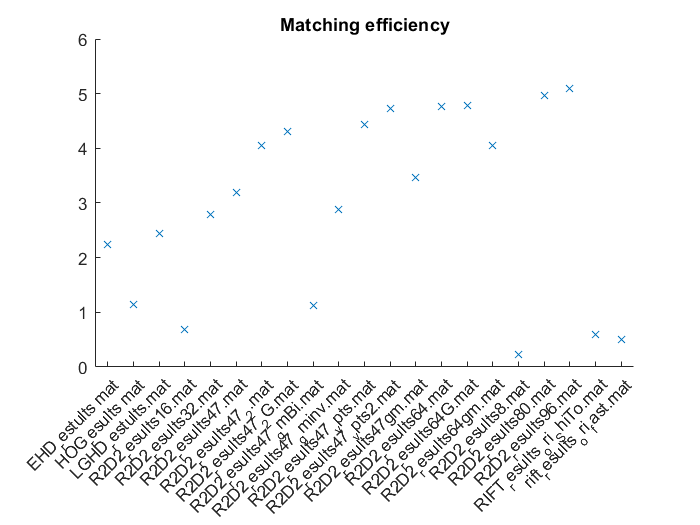

figure, hold on, plot(X,matchingeff,'x'), title('Matching efficiency'),hold off;

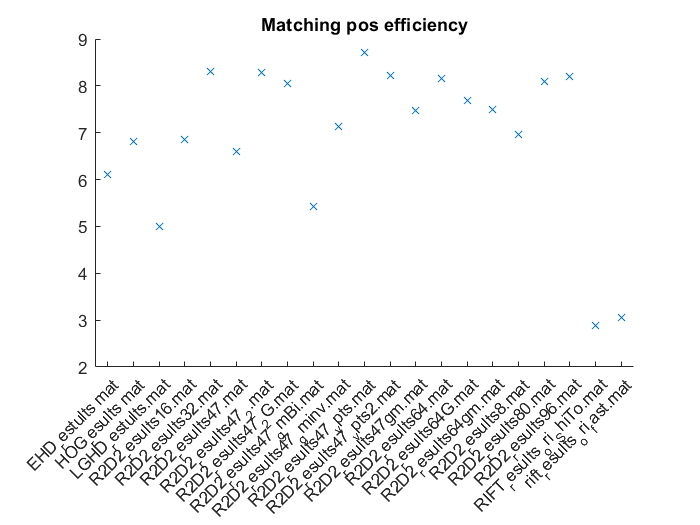

figure, hold on, plot(X,posmatchingeff,'x'), title('Matching pos efficiency'),hold off;

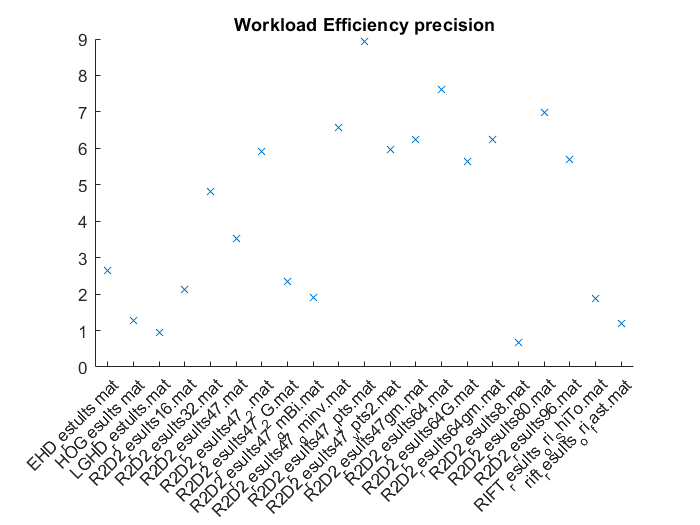

W = workload([1,3,4,5]); W2 = workload2([1,3,4,5]);
figure, hold on, plot(X,workload,'x'), title('Workload Efficiency precision'),hold off;

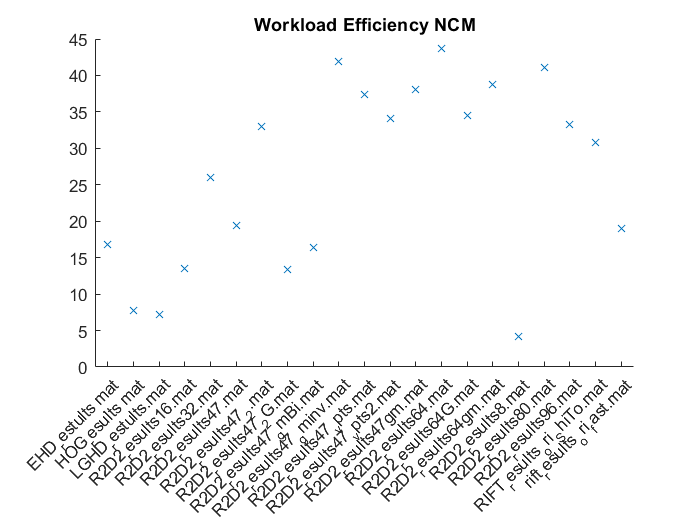

figure, hold on, plot(X,workload_NCM,'x'), title('Workload Efficiency NCM'),hold off;

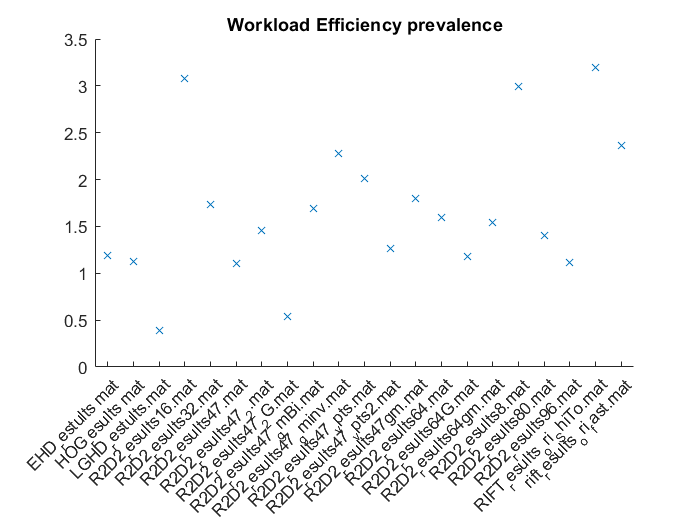

figure, hold on, plot(X,workload_Pre,'x'), title('Workload Efficiency prevalence'),hold off;

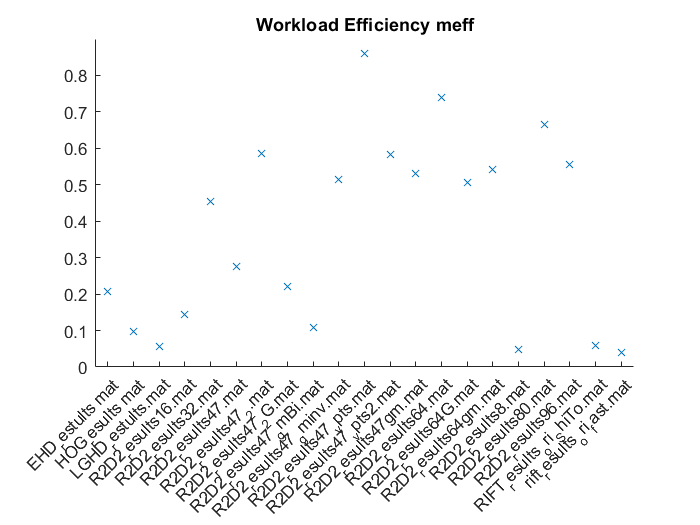

figure, hold on, plot(X,workload_meff,'x'), title('Workload Efficiency meff'),hold off;

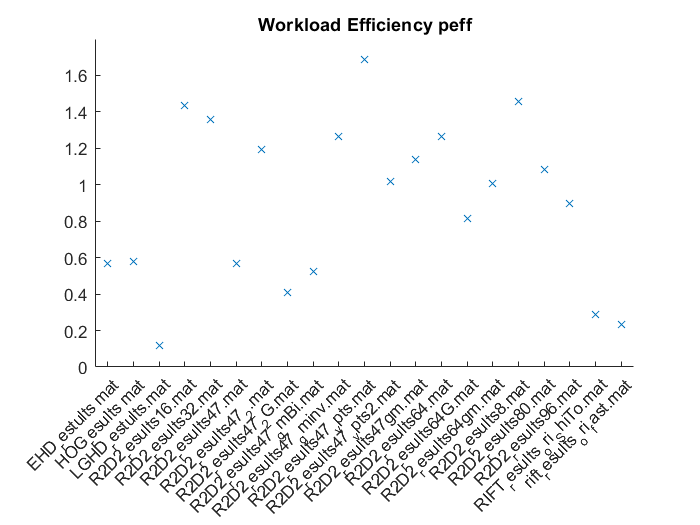

figure, hold on, plot(X,workload_peff,'x'), title('Workload Efficiency peff'),hold off;

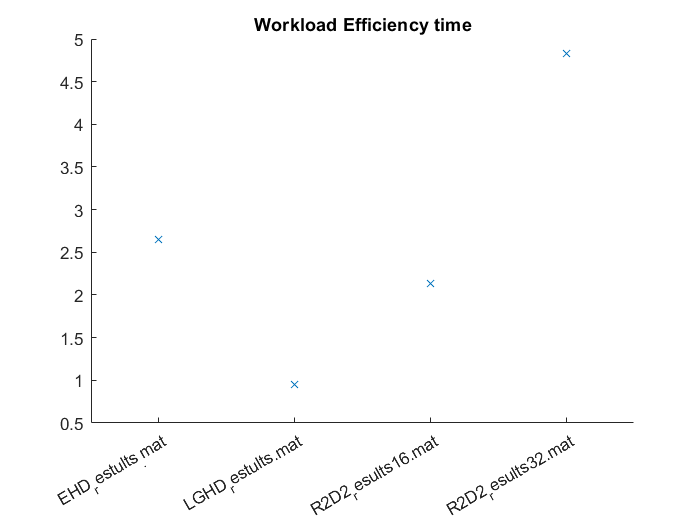

figure, hold on, plot(categorical(methods([1,3,4,5])),W,'x'), title('Workload Efficiency time'),hold off;

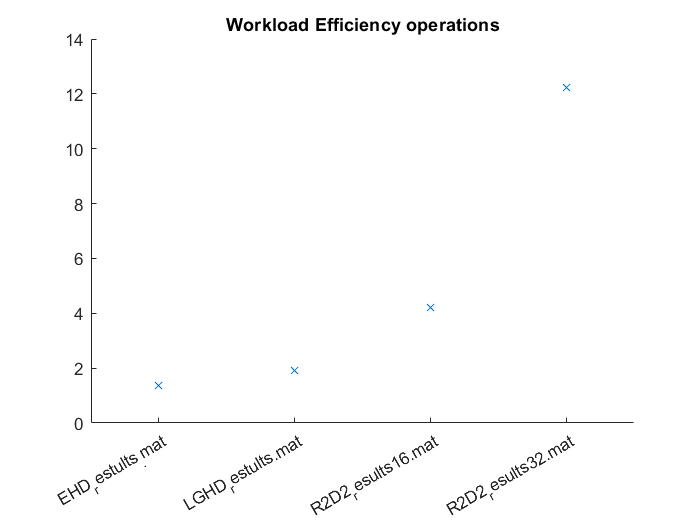

figure, hold on, plot(categorical(methods([1,3,4,5])),W2,'x'), title('Workload Efficiency operations'),hold off;

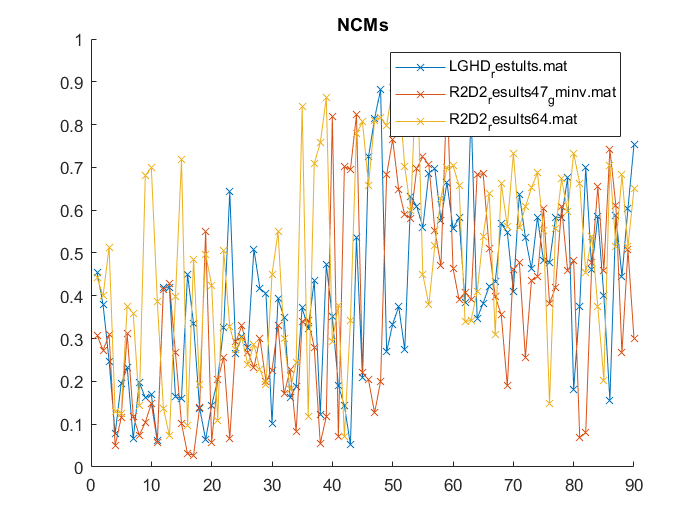

figure, hold on, plot([1:90],pointStats(cats,1:90,4)./pointStats(cats,1:90,3),'x-'),legend(X(cats)) ,title('NCMs'),hold off;

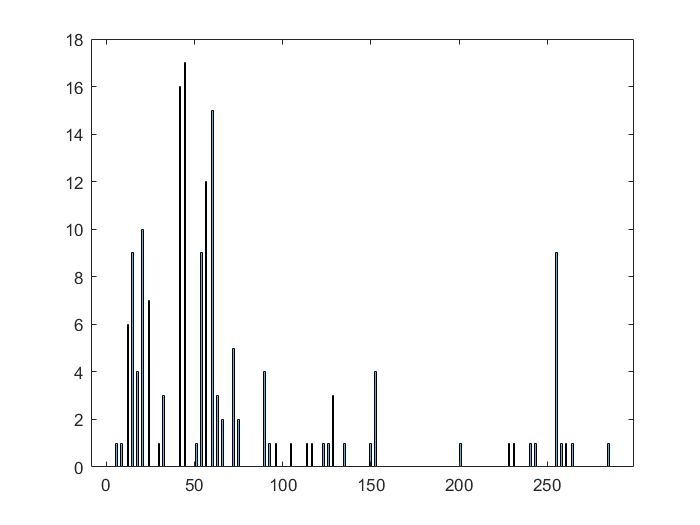

figure,  histogram(bigmiss,303);